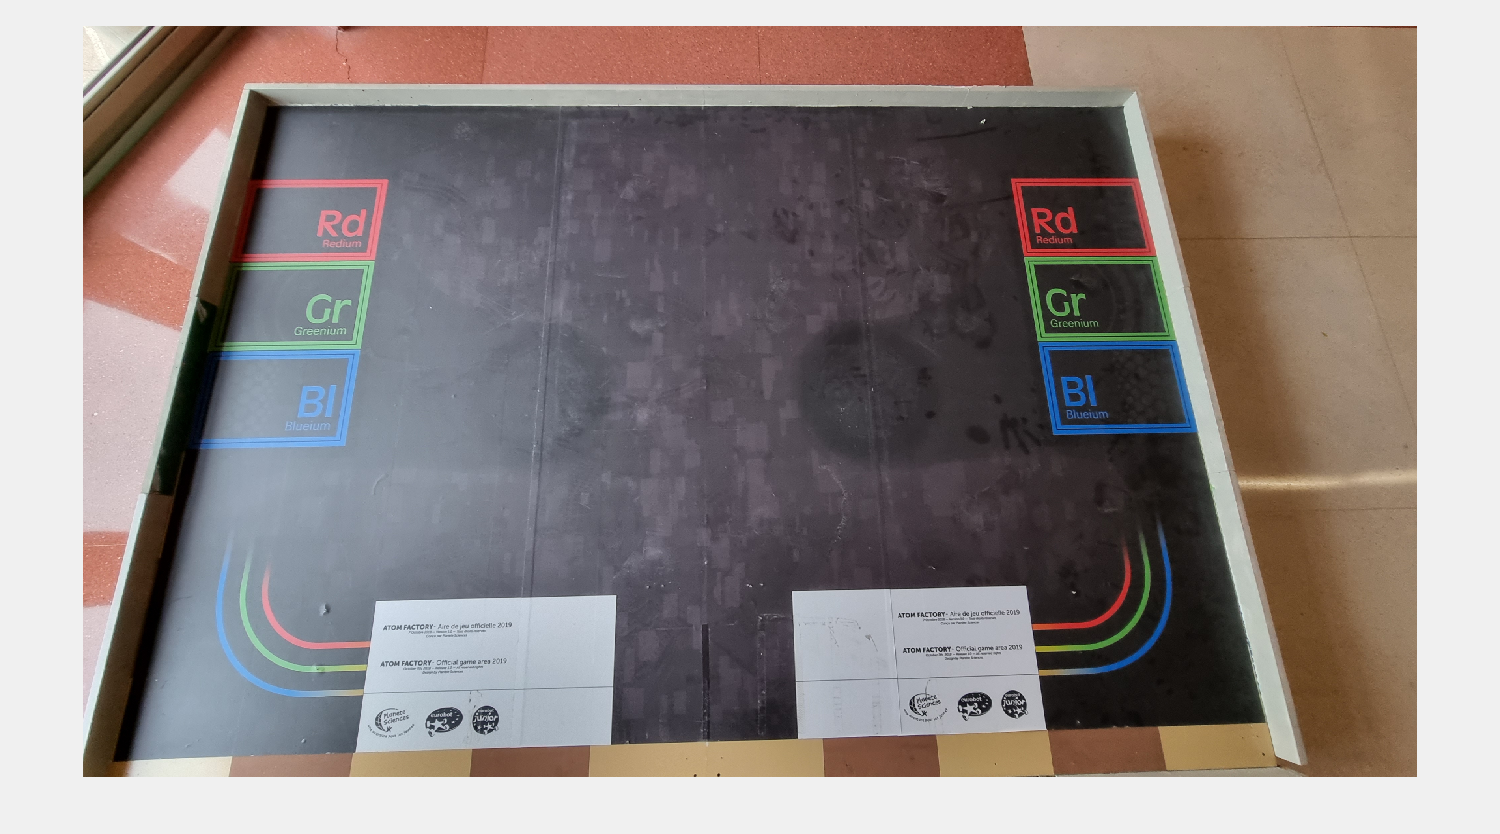

% 1. Cargamos la imagen
I = imread('.\imagenes\pista.jpg');

% 2. Calculamos los puntos de la carta de poquer a la salida
dstPoints = [0 0; 3000 0; 3000 2000; 0 2000];

% 3. Capturamos los puntos de entrada de la carta y estimamos la
% transformacion de perspectiva
figure
[x, y, P] = impixel(I);


srcPoints = [x y];
[tform,inlierIndex,status] = estgeotform2d(srcPoints, dstPoints,'projective');

% 4. Aplicamos la transformacion de perspectiva
destino = imwarp(I,tform);

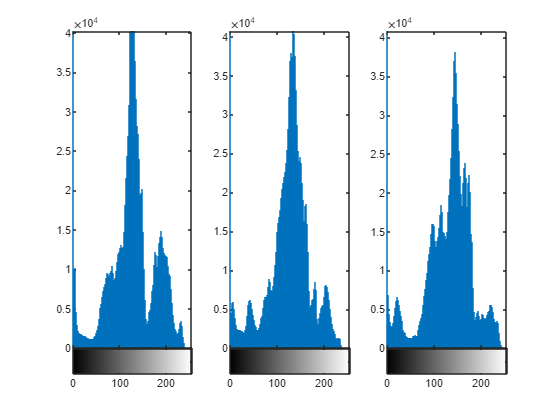

canal_rojo = destino(:,:,1);
canal_verde = destino(:,:,2);
canal_azul = destino(:,:,3);

[m,n,~] = size(destino);
roi_columnas = round(n/8):round(2*(n/6));

figure, 
subplot(1,3,1), imhist(canal_rojo(:, roi_columnas));
subplot(1,3,2), imhist(canal_verde(:, roi_columnas));
subplot(1,3,3), imhist(canal_azul(:, roi_columnas));

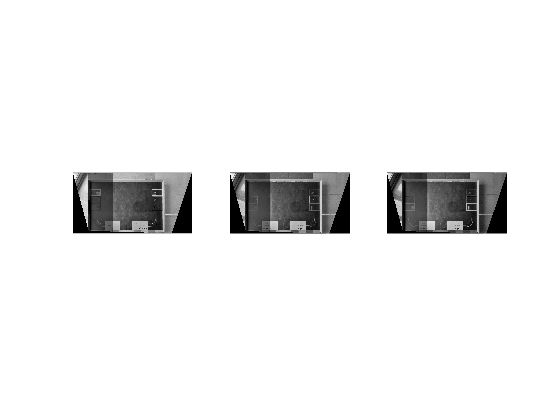


canal_rojo(:, roi_columnas) = imadjust(canal_rojo(:, roi_columnas), [0,1], [0, 0.5]);
canal_verde(:, roi_columnas) = imadjust(canal_verde(:, roi_columnas), [0,1], [0, 0.5]);
canal_azul(:, roi_columnas) = imadjust(canal_azul(:, roi_columnas), [0,1], [0, 0.5]);

figure, 
subplot(1,3,1), imshow(canal_rojo);
subplot(1,3,2), imshow(canal_verde);
subplot(1,3,3), imshow(canal_azul);

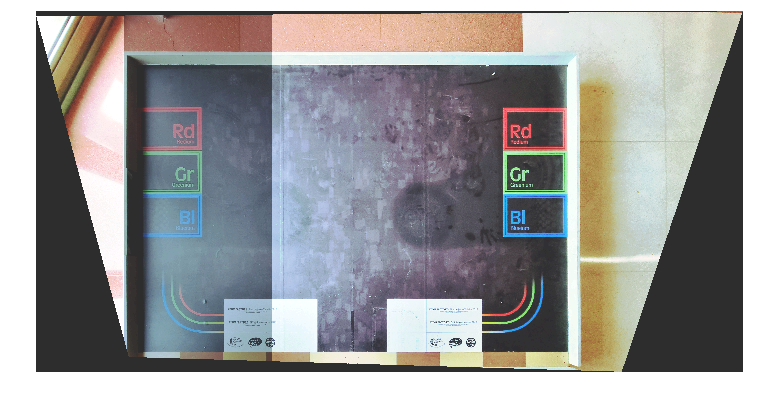


canal_rojo_equalizado = histeq(canal_rojo);
canal_verde_equalizado = histeq(canal_verde);
canal_azul_equalizado = histeq(canal_azul);

imagen_equalizada = cat(3, canal_rojo_equalizado, canal_verde_equalizado, canal_azul_equalizado);

% Mostramos el resultado
figure; imshow(imagen_equalizada);

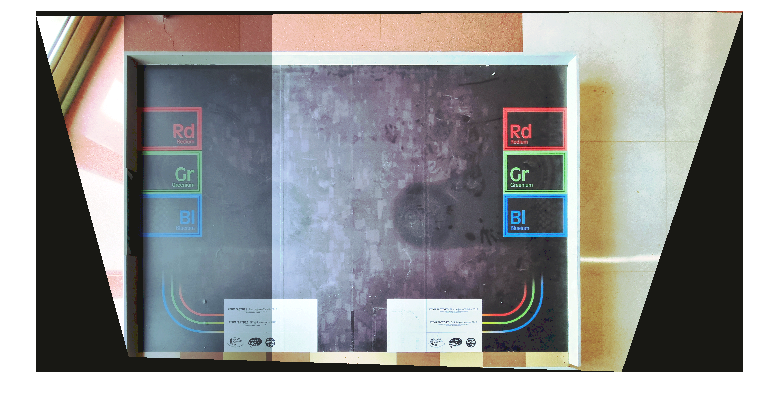

rr = histeq(imagen_equalizada(:,:,1));
gg = histeq(imagen_equalizada(:,:,2));
bb = histeq(imagen_equalizada(:,:,3));

final = cat(3, rr, gg, bb);

figure, imshow(final)